%añadir capa para que acepte imagenes de distintos formatos y formatos de color y tamaños
%5. Implemente un programa que realice la segmentación supervisada por modelos gaussianos (no lineal) para imágenes de cualquier tamaño y tipo (indexadas, color y en niveles de gris)
%que serán siempre convertidas a niveles de gris en primer lugar. 
imread('rice.tif');
imfinfo('rice.tif')%Información sobre la imagen

ans = struct with fields:
                     Filename: 'D:\UAH\4º\SISTEMAS DE VISIÓN ARTIFICIAL\3\pecl3\rice.tif'
                  FileModDate: '05-oct.-2017 22:04:46'
                     FileSize: 65966
                       Format: 'tif'
                FormatVersion: []
                        Width: 256
                       Height: 256
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'Uncompressed'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [8 8200 16392 24584 32776 40968 49160 57352]
              SamplesPerPixel: 1
                 RowsPerStrip: 32
              StripByteCounts: [8192 8192 8192 8192 8192 8192 8192 8192]
                  XResolution: 72
                  YResolution: 72
               ResolutionUnit: 'Inch'
     

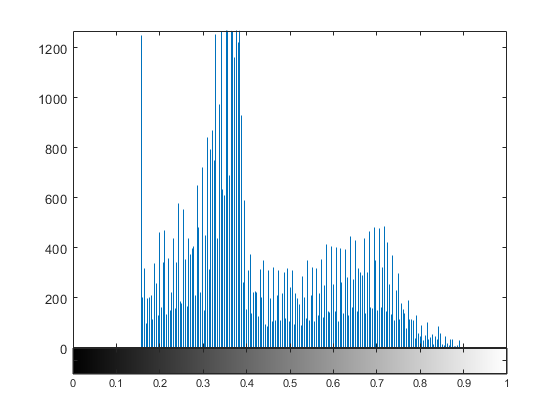

X=im2double(imread('rice.tif')); %Imagen cuadrada de 256x256; length(X)=256;
figure;
imhist(X);

disp('Selecciona 1º, con el raton (botón izqu.), unos cuantos pixels de fondo.  Luego enter.'); 

Selecciona 1º, con el raton (botón izqu.), unos cuantos pixels de fondo.  Luego enter.


disp( 'Selecciona después  unos cuantos pixels de objetos. Luego enter');

Selecciona después  unos cuantos pixels de objetos. Luego enter


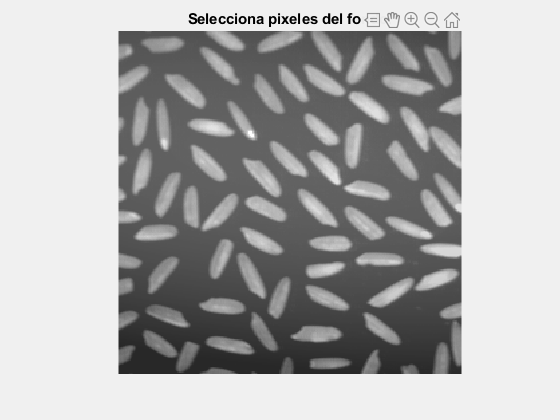

val =     0.3843    0.3843    0.3843
    0.3843    0.3843    0.3843
    0.3765    0.3765    0.3765
    0.3725    0.3725    0.3725
    0.3059    0.3059    0.3059
    0.2588    0.2588    0.2588
    0.3137    0.3137    0.3137


val=impixel(X),title('Selecciona pixeles del fondo.'); 

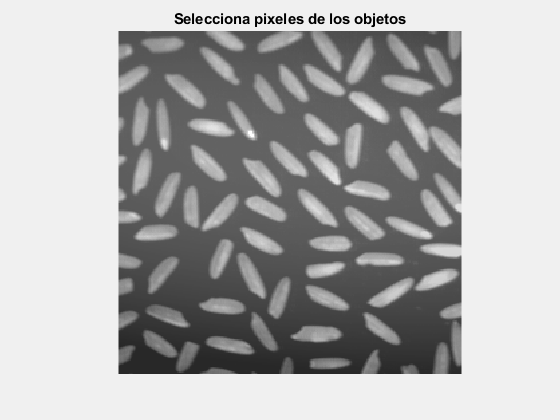

val =     0.8392    0.8392    0.8392
    0.8902    0.8902    0.8902
    0.7098    0.7098    0.7098
    0.8745    0.8745    0.8745
    0.7843    0.7843    0.7843
    0.6980    0.6980    0.6980
    0.6078    0.6078    0.6078


fondo=val; 
val=impixel(X),title('Selecciona pixeles de los objetos'); 

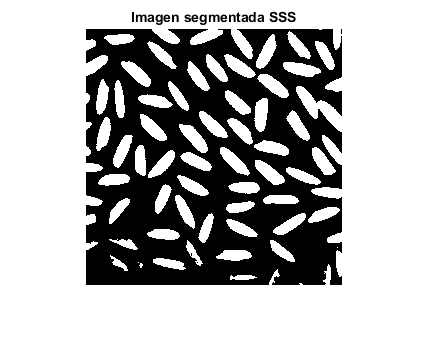

granos=val; 
mf=mean(fondo(:,1));  %Media de la clase fondo
mg=mean(granos(:,1)); %Media de la clase grano 
sf=std(fondo(:,1));   %Desviacion tipica de la clase fondo
sg=std(granos(:,1));  %Desviacion tipica de la clase grano
tic %para computar cuanto tarda este algoritmo desde este punto 
SSS=zeros(length(X),length(X)); %Imagen a segmentar  inicializada ceros(fondo -> todo negro)        
        bayesf_total=(1/(sqrt(2*pi)*sf))*exp(-0.5*(X-mf)*sf^(-2).*(X-mf)); %fdp normal         
    bayesg_total=(1/(sqrt(2*pi)*sg))*exp(-0.5*(X-mg)*sg^(-2).*(X-mg)); %fdp normal         
    SSS= (bayesg_total > bayesf_total); 
figure,imshow(SSS); 
title('Imagen segmentada SSS'); 

toc %devuelve cuanto tardo el algoritmo desde el inicio del tic 

Elapsed time is 0.207291 seconds.
